load('Sparse_Low_Rank_dataset.mat');
N = 32;

sample_indices = 1:15;   
num_trials = 15;         
M = 300;                 
lambda1 = 0.1;          
lambda2 = 0.01;           
maxIter = 300;

all_errors = zeros(length(sample_indices), num_trials);

for s = 1:length(sample_indices)
    k = sample_indices(s);
    H_true = reshape(H(:,:,k), [N,N]);

    for t = 1:num_trials
      
        Omega = randperm(N^2, M);
        mask = false(N,N);
        mask(Omega) = true;
        y = H_true(mask);

        H_hat = ista_sparse_lowrank(y, mask, N, lambda1, lambda2, maxIter);

        err = (norm(H_hat - H_true, 'fro'))^2 / (norm(H_true, 'fro'))^2;
        all_errors(s, t) = err;

    end
end

mean_per_sample = mean(all_errors, 2);     
std_per_sample  = std(all_errors, 0, 2);   
overall_avg     = mean(mean_per_sample);   
overall_std     = std(mean_per_sample);    

fprintf('\n=== Summary over %d samples × %d trials ===\n', ...
        length(sample_indices), num_trials);


=== Summary over 15 samples × 15 trials ===


fprintf('Overall Average Relative Error: %.4f ± %.4f\n', overall_avg, overall_std);

Overall Average Relative Error: 0.0060 ± 0.0022


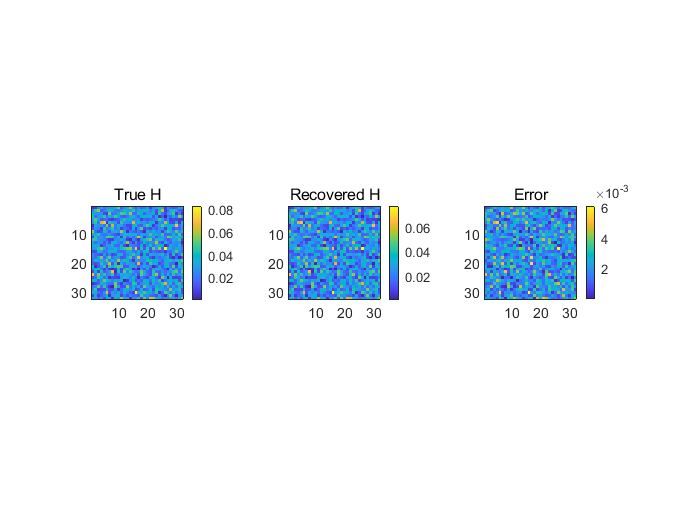

Reconstruction Relative Error: 0.0058


    figure;
    subplot(1,3,1); imagesc(abs(H_true)); title('True H'); axis image; colorbar;
    subplot(1,3,2); imagesc(abs(H_hat)); title('Recovered H'); axis image; colorbar;
    subplot(1,3,3); imagesc(abs(H_true - H_hat)); title('Error'); axis image; colorbar;

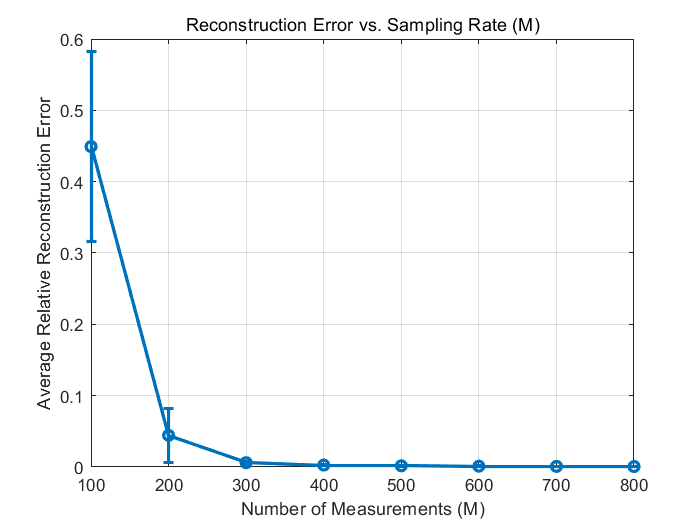

Ms = [100 200 300 400 500 600 700 800];  
lambda1 = 0.1;
lambda2 = 0.01;
maxIter = 300;

sample_indices = 1:15;
num_trials = 15;
N = 32;

avg_errors_M = zeros(length(Ms), 1); 
avg_times_M   = zeros(length(Ms), 1);
avg_memory_M  = zeros(length(Ms), 1);


for m_idx = 1:length(Ms)
    M = Ms(m_idx); 

    all_errors = zeros(length(sample_indices), num_trials);  
    all_times  = zeros(length(sample_indices), num_trials);
    all_memory = zeros(length(sample_indices), num_trials);

    for s = 1:length(sample_indices)
        k = sample_indices(s);
        H_true = reshape(H(:,:,k), [N,N]);

        for t = 1:num_trials
            Omega = randperm(N^2, M);
            mask = false(N,N);
            mask(Omega) = true;
            y = H_true(mask);
            
            tic;
     
            [H_hat, mem_kb] = ista_sparse_lowrank(y, mask, N, lambda1, lambda2, maxIter);
            elapsed = toc;

            err = norm(H_hat - H_true, 'fro')^2 / norm(H_true, 'fro')^2;
            all_errors(s, t) = err;
            all_times(s,t)  = elapsed;
            all_memory(s,t) = mem_kb;
        end
    end

    mean_per_sample = mean(all_errors, 2);
    mean_time_per_sample = mean(all_times, 2);
    mean_memory_per_sample = mean(all_memory, 2);   
    avg_errors_M(m_idx) = mean(mean_per_sample);
    avg_times_M(m_idx)  = mean(mean_time_per_sample);
    avg_memory_M(m_idx) = mean(mean_memory_per_sample);

    std_errors_M(m_idx) = std(mean_per_sample);
    
   
end

figure;
errorbar(Ms, avg_errors_M, std_errors_M, '-o', 'LineWidth', 2);
xlabel('Number of Measurements (M)');
ylabel('Average Relative Reconstruction Error');
title('Reconstruction Error vs. Sampling Rate (M)');
grid on;

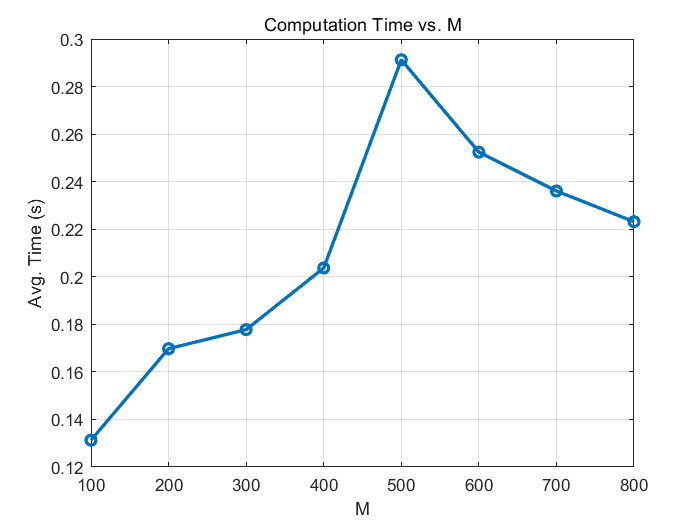

figure;
plot(Ms, avg_times_M, '-o', 'LineWidth', 2);
xlabel('M'); ylabel('Avg. Time (s)');
title('Computation Time vs. M');
grid on;

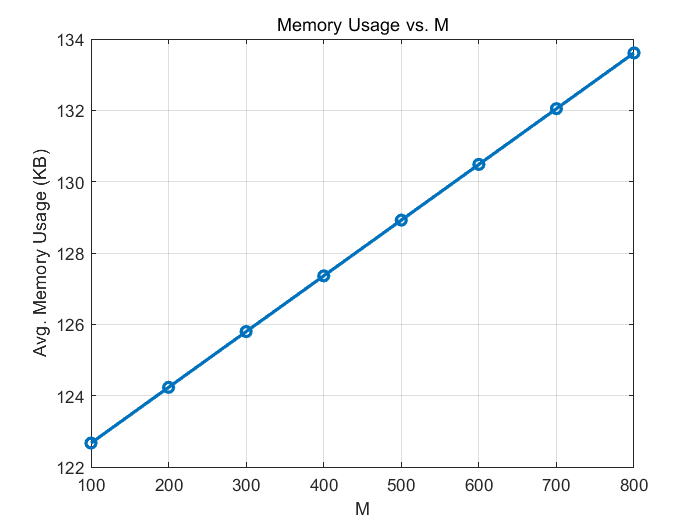


figure;
plot(Ms, avg_memory_M, '-o', 'LineWidth', 2);
xlabel('M'); ylabel('Avg. Memory Usage (KB)');
title('Memory Usage vs. M');
grid on;

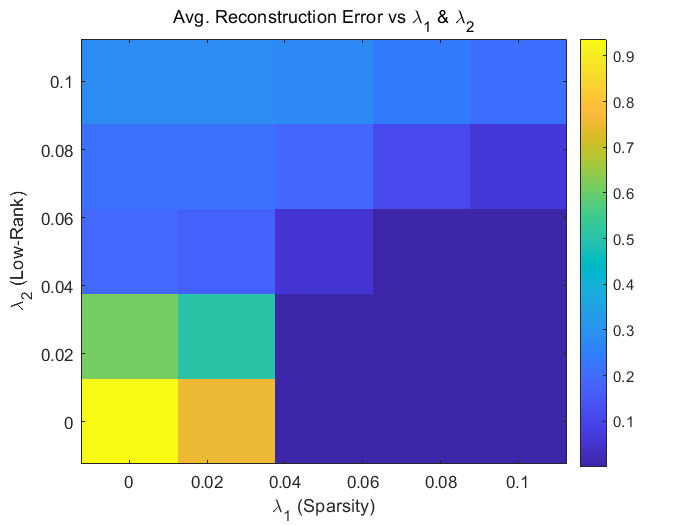

lambda1_list = [0.0001, 0.001, 0.01, 0.05, 0.1];   
lambda2_list = [0.0001, 0.001, 0.01, 0.05, 0.1];   
num_l1 = length(lambda1_list);
num_l2 = length(lambda2_list);
error_matrix = zeros(num_l2, num_l1);  
time_matrix   = zeros(num_l2, num_l1);
memory_matrix = zeros(num_l2, num_l1);


sample_indices = 1:15;     
num_trials = 15;            
N = 32;                     
M = 500;                    
maxIter = 300;              

for i = 1:num_l1
    for j = 1:num_l2
        lambda1 = lambda1_list(i);
        lambda2 = lambda2_list(j);

        all_errors = zeros(length(sample_indices), num_trials);
        all_times  = zeros(length(sample_indices), num_trials);
        all_memory = zeros(length(sample_indices), num_trials);


        for s = 1:length(sample_indices)
            k = sample_indices(s);
            H_true = reshape(H(:,:,k), [N,N]);

            for t = 1:num_trials
                Omega = randperm(N^2, M);
                mask = false(N,N);
                mask(Omega) = true;
                y = H_true(mask);

                tic;

                [H_hat, mem_kb] = ista_sparse_lowrank(y, mask, N, lambda1, lambda2, maxIter);
                elapsed = toc;

                err = (norm(H_hat - H_true, 'fro'))^2 / (norm(H_true, 'fro'))^2;
                all_errors(s,t) = err;
                all_times(s,t)  = elapsed;
                all_memory(s,t) = mem_kb;
            end
        end

        mean_per_sample = mean(all_errors, 2);
        avg_error = mean(mean_per_sample);
        error_matrix(j,i) = avg_error;  
        mean_time_per_sample = mean(all_times, 2);
        mean_memory_per_sample = mean(all_memory, 2);
        avg_times = mean(mean_time_per_sample);
        avg_memory = mean(mean_memory_per_sample);
        time_matrix(j,i)   = avg_times;
        memory_matrix(j,i) = avg_memory;
    end
end

figure;
imagesc(lambda1_list, lambda2_list, error_matrix);  % X: λ1, Y: λ2
colorbar;
xlabel('\lambda_1 (Sparsity)');
ylabel('\lambda_2 (Low-Rank)');
title('Avg. Reconstruction Error vs \lambda_1 & \lambda_2');
set(gca, 'YDir','normal');  

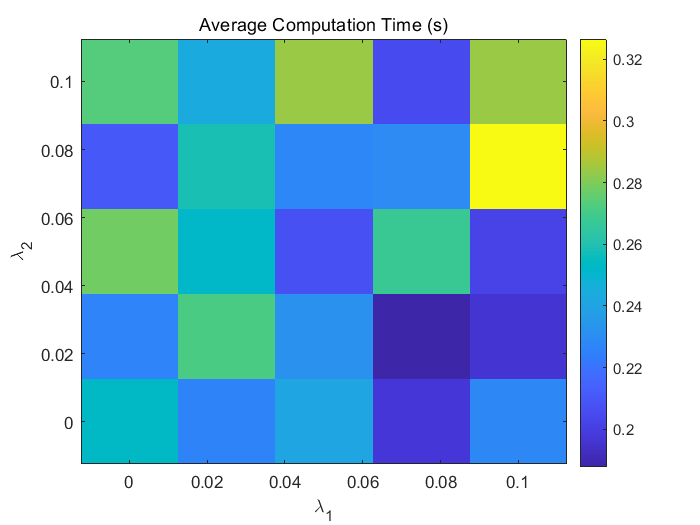

figure;
imagesc(lambda1_list, lambda2_list, time_matrix); colorbar;
xlabel('\lambda_1'); ylabel('\lambda_2');
title('Average Computation Time (s)'); set(gca, 'YDir','normal');

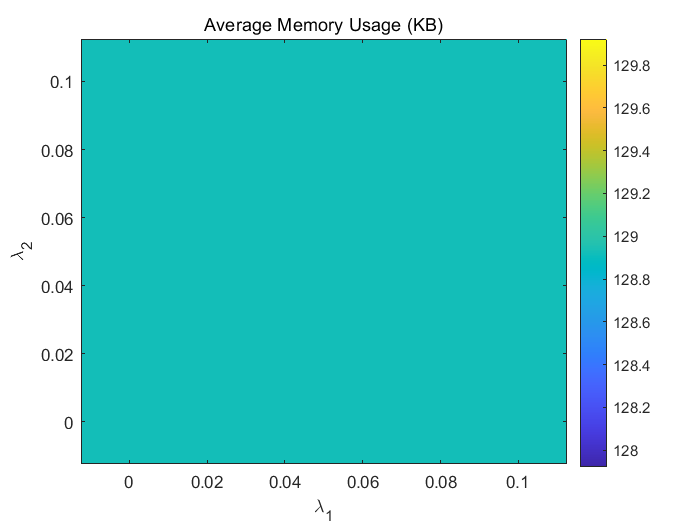


figure;
imagesc(lambda1_list, lambda2_list, memory_matrix); colorbar;
xlabel('\lambda_1'); ylabel('\lambda_2');
title('Average Memory Usage (KB)'); set(gca, 'YDir','normal');

function [H, mem_kb] = ista_sparse_lowrank(y, mask, N, lambda1, lambda2, maxIter)
    H = zeros(N,N);
    tau = 1; 

    F = @(X) fft2(X);   
    Fi = @(X) ifft2(X);  

    for t = 1:maxIter
        % --- Gradient Step ---
        grad = zeros(N,N);
        grad(mask) = 2*(H(mask) - y);
        H_temp = H - tau * grad;

        % --- Prox Step 1: Sprasity（DFT-L1） ---
        Z = F(H_temp);
        Z = soft_threshold(Z, lambda1 * tau);
        H_s = Fi(Z);

        % --- Prox Step 2: Low-rankness（Nuclear norm） ---
        [U,S,V] = svd(H_s, 'econ');
        S = diag(soft_threshold(diag(S), lambda2 * tau));
        H = U * S * V';

    end
    vars = whos;
    total_bytes = sum([vars.bytes]);
    mem_kb = total_bytes / 1024;
end

function X = soft_threshold(X, thresh)
    X = sign(X) .* max(abs(X) - thresh, 0);
end
